## **Curve fitting and parameter calibration - Jón Sveinbjörn Halldórsson**

### Linear least square fitting

x = [0 1 2 3 4 5 6 7 8 9 10];
y = [2 2.3 2.4 2.7 2.9 3.0 3.2 3.3 3.6 3.5 4.0];
[a,b] = linearleastsquarefitting(x,y)

a = 0.1809

b = 2.0864

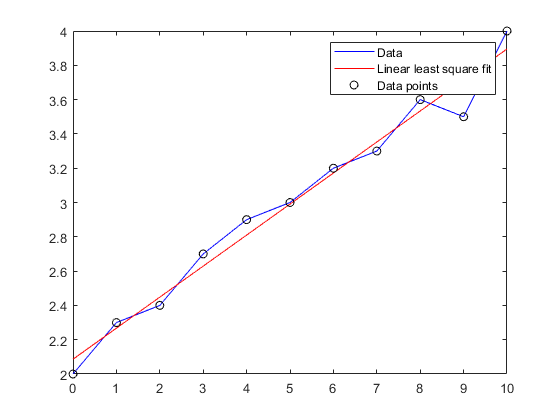

f = @(z) a*z + b;
z = 0:10;
plot(x,y,'b',z,f(z),'r',x,y,'ko')
legend('Data','Linear least square fit','Data points')

### Polynomial least square fitting

x = 0:10;
y = [3.2 2.7 2.6 2.4 2.3 2.4 2.65 2.8 2.9 3.1 3.2];
[a]  = polyleastsquarefitting(x,y,2)

a =     3.0308
   -0.2646
    0.0298


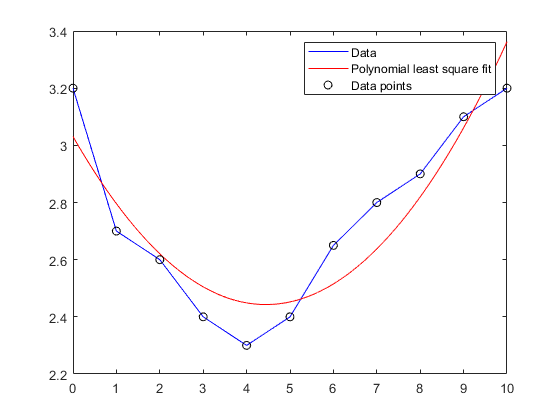

xx = 0:0.001:100;
f = @(xx) a(1)+a(2).*xx+a(3)*xx.^2;
plot(x,y,'b',xx,f(xx),'r',x,y,'ko')
xlim([0 10])
legend('Data','Polynomial least square fit','Data points')

### Lagrange Interpolation

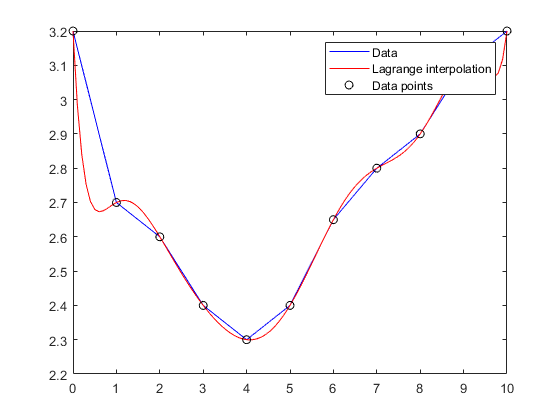

xx = linspace(0,10);
yy = lagrangeinterpolation(xx,x,y);
plot(x,y,'b',xx,yy,'r',x,y,'ko')
legend('Data','Lagrange interpolation','Data points')

### Spline and cubic smoothing spline

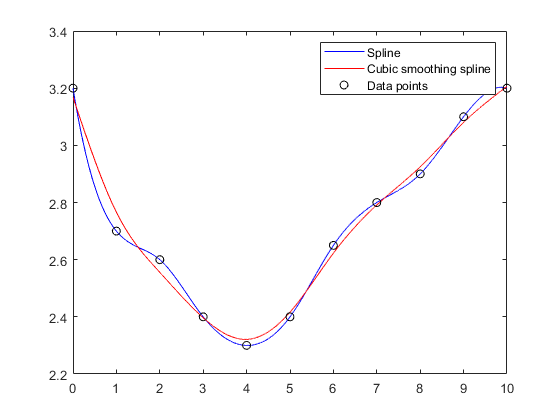

sp = spline(x,y);
cs = csaps(x,y);
xsp = 0:0.001:10;
plot(xsp,ppval(sp,xsp),'b',xsp,ppval(cs,xsp),'r',x,y,'ko')
legend('Spline','Cubic smoothing spline','Data points')

### Maximum likelihood estimation

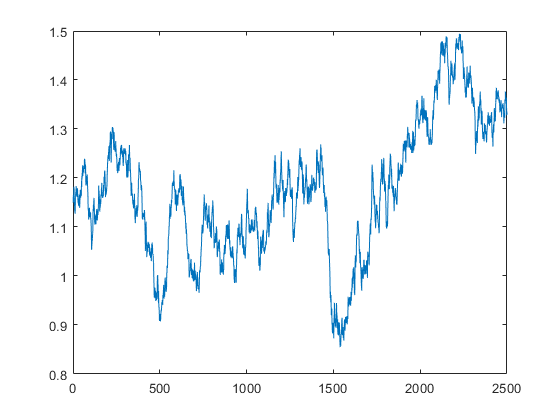

k = 0.25;
theta = 1.25;
sigma = 0.2;
s0 = 1.15;
dt = 1/250;
T = 10;
S = SIM_OU(k,theta,sigma,s0,dt,T);
plot(S)

[theta_s, k_s, sigma_s] = MLE_OUest(S,dt)

theta_s = 1.1886

k_s = 0.9429

sigma_s = 0.1965